# Taking Transects

This MATLAB LiveScript serves as a live document to create the algorithm to take the transects of SAR data required in the SAR Ice Pipeline. 

## 1 Import the CosmoSkyMED Data

### 1.1 Import from file

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/MSc/subset_CSKS1_DGM_B_WR_01_VV_RA_SF_20220722070221_20220722070237_small.nc";

ncInfo_SAR = ncinfo(filepath);
% Create a cosmo satellite object to store all important information.
cosmo = CosmoSkyMED(filepath,"CSK");

% Import the data.
%sarData = ncread(cosmo.Filepath,'Amplitude');
sar_latGrid = ncread(cosmo.Filepath,'lat')';
sar_lonGrid = ncread(cosmo.Filepath,'lon')';
sar_Data_import = ncread(cosmo.Filepath,'Intensity')'; 
sar_Data = sar_Data_import/mean(sar_Data_import(:)); % Normalise the intensity values to a value between 0 and 1.

[sar_start_datetime,sar_stop_datetime] = cosmo.getAcquisitiontime(); 


Alternatively, import the data as an hdf5 file.

% filepath = "/Users/tris/Documents/MATLAB/MSc/20220722_1778608_CSG_/CSG_SSAR1_DGM_B_0301_SC1_001_VV_RA_F_20220722065043_20220722065057_1_F_57S_Z31_N00.h5";
% 
% h5Info = h5info(filepath);
% 
% % Create a structure to store imported HDF5 data
% sarData = h5read(filepath, '/IMG');
% % Display results
% figure; imshow(sarData);

### 1.2 View SAR Data

Choose whether to display a greyscale image of the imported SAR data.

% % plotSARData = true;
% figure;
% pcolor(sar_lonGrid, sar_latGrid, sar_Data);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% title("COSMO-SkyMed (X-band) No Cal SAR image - 22/07/2022")
% ylabel("Latitude");
% xlabel("Longitude");

### 1.3 Radiometric Calibration

sar_Data_cal = cosmo.radiometricCalibration(sar_Data); 
sar_Data_cal = sar_Data_cal/mean(sar_Data_cal(:)); % Normalise the intensity values to a value between 0 and 1.

figure;
pcolor(sar_lonGrid,sar_latGrid,sar_Data_cal);
shading("flat");
colormap("gray");
clim([0 2]);
title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
ylabel("Latitude");
xlabel("Longitude");

## 2 Open Ocean Transect

This transect needs to be absent of any ice i.e. completely open ocean.

****TO DO**: Come up with a smart way of doing open ocean detection when selecting the first transect. 

sar_transect_size = 512; % This is the standard size used.

### **2.1 Define Points of Interest / Transect**

These are the top left corner point of the OO transect.

latitude_of_interest = -58.59;
longitude_of_interest = -1.1;

### 2.2 Create the OO Transect

Now we need to find the indexes. Note that in matlab dimension are row by columns = y by x = latitude by longitude

sar_transect_lat_start_index = find(floor(sar_latGrid(:,1)*100)/100 == latitude_of_interest);
sar_transect_lat_end_index = sar_transect_lat_start_index - sar_transect_size -1;

sar_transect_lon_start_index = find(floor(sar_lonGrid(sar_transect_lat_start_index(1),:)*100)/100==longitude_of_interest);
sar_transect_lon_end_index = sar_transect_lon_start_index + sar_transect_size -1;

sar_transect = sar_Data_cal(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_lonGrid = sar_lonGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));
sar_transect_latGrid = sar_latGrid(sar_transect_lat_end_index(1):sar_transect_lat_start_index(1),sar_transect_lon_start_index(1):sar_transect_lon_end_index(1));

% % Plot the transect on the original image
% figure;
% pcolor(sar_lonGrid,sar_latGrid,sar_Data_cal);
% shading("flat");
% colormap("gray");
% clim([0 2]);
% hold on;
% pcolor(sar_transect_lonGrid, sar_transect_latGrid, sar_transect);
% hold off;

% Plot the transect 
figure;
pcolor(sar_transect_lonGrid, sar_transect_latGrid, sar_transect);
shading("flat");
colormap("gray");
clim([0 2]);

### 2.3 Update the latitudes and longitudes

start_latitude= sar_transect_latGrid(1,1);
stop_latitude= sar_transect_latGrid(sar_transect_size,sar_transect_size);
start_longitude = sar_transect_lonGrid(1,1);
stop_longitude = sar_transect_lonGrid(sar_transect_size,sar_transect_size);

## 3 ERA5 Data

This is wave model data. We need to subdivide it to get the matching time, date, lattitudes and longitudes of our SAR data. The larger data then also needs to be sliced so that we can get the data matching the OO transect.

Finally, we need to calculate or use the mean wave direction so that are able to subdivide the SAR image into transects that flow into the ice.

### 3.1 Download

Get this from the CDS_ERA5_datahandling.mlx script. ****TO DO**: Make it adjustable so that the correct date and time data can be downloaded.

### 3.2 Import the data from the file

The data needs to be 'decoded' according to the ERA5 documentation:  [https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation](https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation)

Specifically:

"

The NetCDF wave spectra file will have the dimensions longitude, latitude, direction, frequency and time.

However, the direction and frequency bins are simply given as 1 to 24 and 1 to 30, respectively.

The **direction bins** start at 7.5 degree and increase by 15 degrees until 352.5, with 90 degree being towards the east (Oceanographic convention).

The **frequency bins** are non-linearly spaced. The first bin is 0.03453 Hz and the following bins are: f(n) = f(n-1)*1.1; n=2,30. 

The data provided is the log10 of spectra density. To obtain the spectral density one has to take to the power 10 (10 ** data). This will give the units 2D wave spectra as m**2 s radian**-1 . Very small values are discarded and set as missing values. These are essentially 0 m**2 s radian**-1.

This recoding can be done with the Python [xarray](http://xarray.pydata.org/en/stable/) package, for example:

**Units of 2D wave spectra**

Once decoded, the units of 2D wave spectra are m2 s radian-1

"

%% Get Parameters of the complete 
filepath = "/Users/tris/Documents/MATLAB/MSc/ERA5-2Dws_20220720.nc";

% Store file info in MATLAB struct
ncinfo_era5 = ncinfo(filepath);

% Get attributes
era5_lon = ncread(filepath,'longitude');
era5_lat = ncread(filepath,'latitude');
era5_time_epoch = ncread(filepath,'time');
era5_direction = ncread(filepath,'direction');
era5_frequency = ncread(filepath,'frequency');
era5_d2fd_all_5dims = ncread(filepath,'d2fd'); % 'frequency direction spectrum' Wave energy spectrum OR variance density spectrum [m^2 s / rad] : how the wave energy is distributed across different spatial and temporal scales

% Decode the direction data according to the ERA5 documentation
era5_direction_bins = ((7.5: 15: 352.5)/180*pi)'; % From ERA5 documentation

% Decode the frequency data ERA5 according to https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation
era5_freq_bins = zeros(1, size(era5_frequency,1));
era5_freq_bins(1) = 0.03453;
for i=2:length(era5_freq_bins)
    era5_freq_bins(i) = era5_freq_bins(i-1)*1.1;
end

% Decode the spectra according to the ERA5 documentation
era5_d2fd_all_5dims = 10.^era5_d2fd_all_5dims; % [m^2 s /rad]
era5_d2fd_all_5dims(isnan(era5_d2fd_all_5dims)) = 0; % Necessary step according to the ERA5 documentation

### **3.3 Get the Wave spectrum at similar points to SAR data**

#### **3.3.1 Find the longitude and latitudes that are the closest to the SAR transect**

****TO DO: Need to figure out how to find the matching lat and long positions (round, floor or ceil? based on the first or last pixel location?)**

lat_position_match = find(era5_lat == round(start_latitude));
lon_position_match = find(era5_lon == round(start_longitude));

**3.3.2 Find the time that is the closest to the sar acquisition interval**

Need to calculate the date time version of the ERA5 epoch time given ('hours since 1900-01-01 00:00:00.0'). This is specified in the downloaded data and in the documentation.

% Convert from epoch time to real time values
era5_time = [datetime(2022,07,22,06,00,00);datetime(2022,07,22,07,00,00);datetime(2022,07,22,08,00,00)];
% era5_time = datetime(int64(era5_time_epoch)*3600,'ConvertFrom','epochtime','Epoch','1900-01-01');

% Find the slice that matches the SAR image
era5_date_only = dateshift(era5_time, 'start', 'day');
sar_date_only = dateshift(sar_start_datetime, 'start', 'day');
time_position_match = era5_date_only == sar_date_only;
time_position_match = find(hour(era5_time(time_position_match)) == hour(sar_start_datetime));


**3.3.3 Slice the ERA5 data**

% Slice the data
era5_d2fd(:,:) = era5_d2fd_all_5dims(lon_position_match,lat_position_match,:,:,9);

### **3.4 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

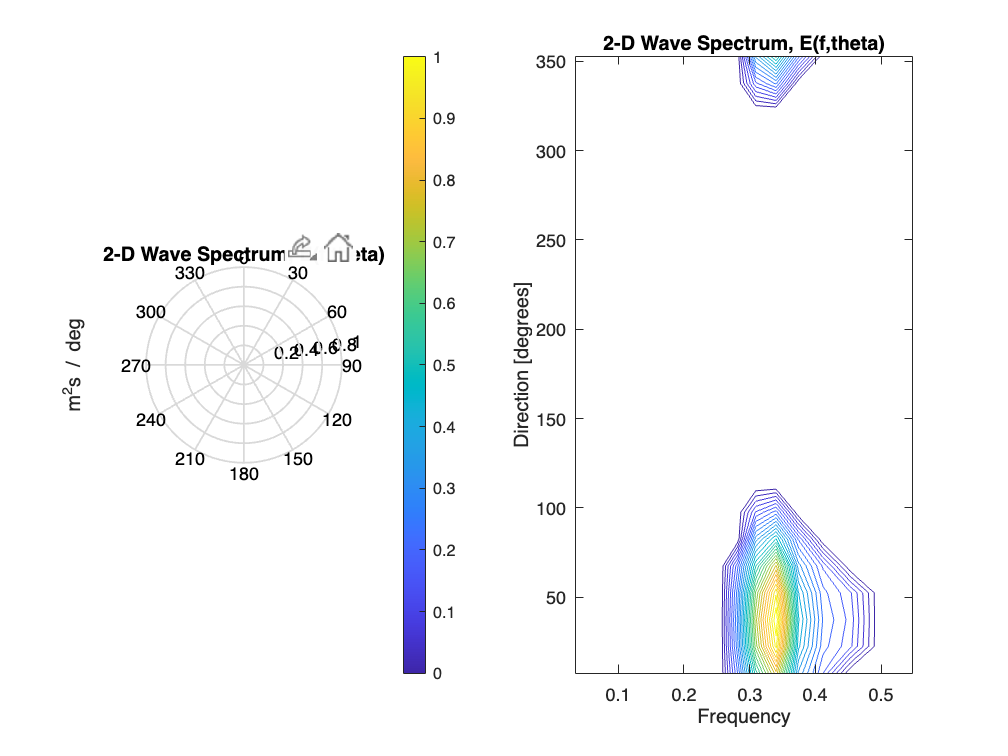

plotERA52Dspectrum = true;
if plotERA52Dspectrum 
    % Plot the 2D spectra
    figure;
    subplot(1,2,1);
    PolarContour(era5_d2fd, era5_freq_bins, 0.2);
    title("2-D Wave Spectrum, E(f,theta)")
    
    subplot(1,2,2);
    contour(era5_freq_bins,era5_direction_bins .* 180/pi,era5_d2fd,30);
    xlabel("Frequency"); ylabel('Direction [degrees]');title("2-D Wave Spectrum, E(f,theta)")
end 

## 4 Calculate the Mean wave direction 

### 4.1 In the chosen OO transect

These equations are taken from ?

#### Significant Wave Height

% Calculate the 0th order moments (m_n) [Eq.8]
era5_m0_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd,2),1); %[Eq.8], dimension 2,3 = direc,freq
% era5_m0_derived_all_time = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
era5_Hs_derived = 4*sqrt(era5_m0_derived); 
% era5_Hs_derived_all_time = 4*sqrt(era5_m0_derived_all_time); 

#### Mean Wave period

% Calculate the -1st order moments (m_n)
era5_m_neg1_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,(1./era5_freq_bins).*era5_d2fd,2),1); %[Eq.8]
% era5_m_neg1_derived_all_time = zeros(size(era5_d2fd_all,5),1);
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:);
%     era5_m_neg1_derived_all_time(t,1) = trapz(era5_direction_bins,trapz(era5_freq_bins,(1/era5_freq_bins).*era5_spectrum_all_time,2),1); %[Eq.8]
% end

% Calculate the mean wave period (Tm) [Eq.5]
era5_Tm_derived = era5_m_neg1_derived/era5_m0_derived; % [Eq.5]
% era5_Tm_derived_all_time = era5_m_neg1_derived_all_time./era5_m0_derived_all_time; % [Eq.5]

#### Mean Wave direction

% Calculate the angular moments [Eq.9&10]
era5_a1 = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins).*era5_d2fd,1),2); %[Eq.9]
era5_b1 = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins).*era5_d2fd,1),2); %[Eq.10]
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:); % dimenstions: direc, freq
%     era5_a1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.9]
%     era5_b1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.10]
% end

% Calculate the mean Direction of the wave
era5_direction_derived = atand(era5_b1./era5_a1); %[Eq.6]
era5_direction_derived_radians = era5_direction_derived * pi/180;
% era5_direction_derived_all_time = atand(era5_b1_all_time./era5_a1_all_time); %[Eq.6]

#### **Spectral Denisty**

% Total variance/energy of the waves = spectral density integrated over all
% frequencies and wave numbers at specified time of interest
% total_variance_or_energy = trapz(trapz(era5_d2fd,2),1);

### 4.2 In the entire acquisition window

## 5 Plot the mean wave direction on the SAR Image & Take transects

https://codes.ecmwf.int/grib/param-db/140230

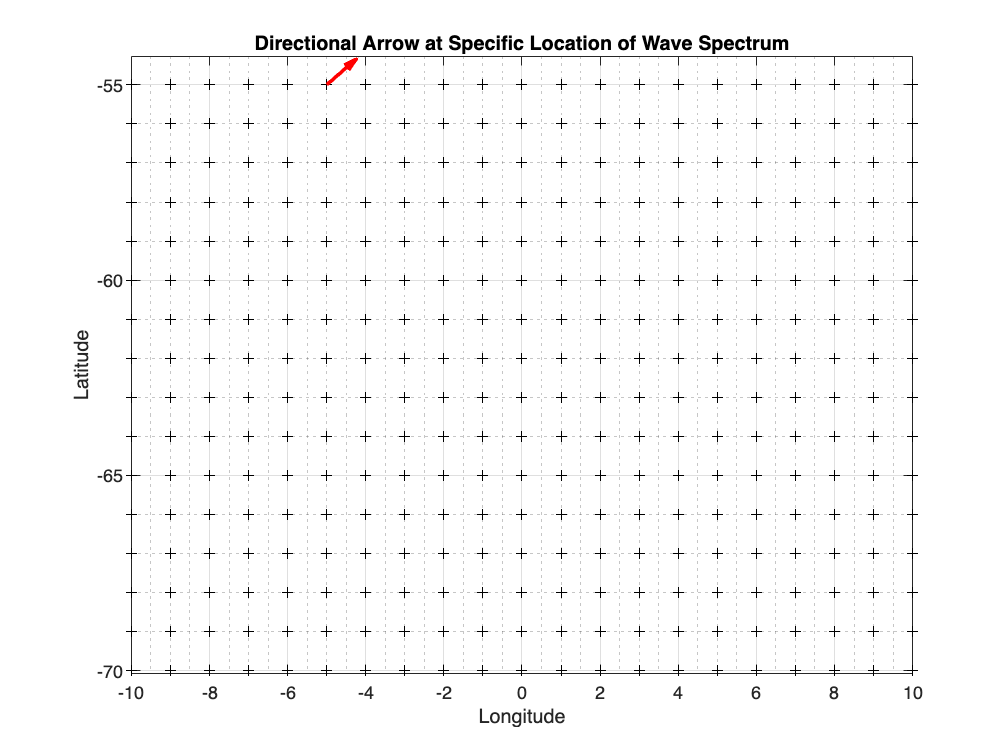

% Plot the Lat-Long x-y grid 
[era5_lonGrid, era5_latGrid] = meshgrid(era5_lon,era5_lat);

% Plot the grid (optional, for context)
figure;
plot(era5_lonGrid, era5_latGrid, "k+");  % Plot grid points for reference
hold on;
% Plot the directional arrow at the specific latitude and longitude
quiver(longitude_of_interest, latitude_of_interest, cos(era5_direction_derived_radians), sin(era5_direction_derived_radians), ...
       'AutoScale', 'off', 'MaxHeadSize', 2, 'LineWidth', 2, 'Color', 'r');

% Adjust plot settings
title('Directional Arrow at Specific Location of Wave Spectrum');
xlabel('Longitude'); ylabel('Latitude');
axis equal;  % Ensure equal scaling of axes
grid on;
grid minor;
hold off;